Preparation

function SharpeRatio = TrendTradingFcnMultiVarSharpe (x, PricesTTinput, VolumesTTinput)
    % Backtest TrendTrading Srategy with MultiVar parameters optimizing
    % Sharpe Ratio
tic

Variable Value Assignment

%LowSkipValTreshCorrection = 
MinValue = x(1) ;
MomContDays = x(2) ; 
MomContRetTrheshold = x(3) ; 
LowLiquidDays = x(4) ;
LowLiquidThreshold = x(5) ;
LiquidSurgThreshold = x(6) ;
MomMainDays = x(7) ;
MomMainRetThreshold = x(8) ;
PostSignalBufferDays = x(9) ;
StopLossLookbackWindSz = x(10) ;
StopLossThreshold = x(11) ;


Paramater Settings

% All Paramaters are set as integers
% LowSkipValTreshCorrection = 10^4 ; % Range from 10 to 10^15
% MinValue = 1*10^9 ; % Range from 0 to 10^15
% MomContDays = 10 ; % Range from 1 to 200
% MomContRetTrheshold = -10; % Range from -50 to 80
% LowLiquidDays = 20 ; % Range from 1 to 200
% LowLiquidThreshold = 10^6 ; % Range from 0 to 10^15
% LiquidSurgThreshold = 20 ; % Range from 0 to 10^15
% LiquidSurgAvgLeadDays = 3 ; % Range from 1 to 200
% LiquidSurgAvgLagDays = 200 ; % Range from 1 to 200
% MomMainDays = 30 ; % Range from 1 to 200
% MomMainRetThreshold = 25 ;  % Range from -50 to 80
% PostSignalBufferDays = 3 ; % Range from 1 to 200
% StopLossLookbackWindSz = 10; % Range from 1 to 200
% StopLossThreshold = 8; % Range from -50 to 80


Sort Symbols Alphabetically 

SymList =  PricesTT.Properties.VariableNames;
SymList = sort (SymList);

PricesTT = PricesTT (:, SymList);
VolumesTT = VolumesTT (:,SymList);

Data cleaning

PricesTTinput ;
VolumesTTinput ;

% Clean price data
PricesTT = fillmissing (PricesTTinput, "previous");
PricesTT = fillmissing (PricesTT, 'next');

% Clean volume data
VolumesTTinputVar = VolumesTTinput.Variables ;

VolumesTTinputVarIdx = VolumesTTinputVar < 100';
VolumeTTFullRawVars (VolumesTTinputVarIdx) = NaN ;
VolumeTTFullRaw.Variables = VolumeTTFullRawVars ;
VolumeTTFull = fillmissing (VolumeTTFullRaw, "previous") ;
IndexTT = fillmissing (IndexTT, "previous");

Transaction Value

PriceTT ;
ValueTT = PriceTT ;
ValueTT.Variables = PriceTT.Variables .* VolumesTT.Variables ;


Liquidity constraints

LiquiditySignal = PriceTT ;
ValueVar = ValueTT.Variables ; 
Signal = ValueVar > MinValue ;
Signal (isnan(Signal)) = 0;
LiquiditySignal.Variables = Signal ;
LiquiditySignal ;

clear ValueVar Signal 

Momentum continuation constraints

MomContDays ;
MomContRetTrheshold ;
MomContSignal = PriceTT ;
Price = PriceTT.Variables ;

MomContRet = Price ;
MomContRet (MomContDays:end, :) = Price (MomContDays:end, :) ./ Price (1:end-MomContDays+1, :) - 1 ;
MomContRet (1:MomContDays -1, :) = 0 ;

MomContSignalVar = MomContRet > MomContRetTrheshold /100 ;
MomContSignalVar (isnan (MomContSignalVar)) = 0;
MomContSignal.Variables = MomContSignalVar;

MomContSignal ;
% Troubleshoot & Check
% max(MomContSignal.Variables)
% max(max(MomContSignal.Variables))
% plot(MomContSignal.Time, MomContSignal.BBCA);

clear MomContSignalVar Price MomContRet 

Avoid inconsistent volume in LowLiquidDays period

LowLiquidSignal = ValueTT ;
LowLiquidSignal.Variables = movmin (ValueTT.Variables, [LowLiquidDays 0]) ;
LowLiquidSignalVar = LowLiquidSignal.Variables ;

LowLiquidSignal.Variables = LowLiquidSignalVar >LowLiquidThreshold ;

% ValueTT
LowLiquidSignal;

%LowLiquidSignalVar < low

% plot (LowLiquidSignal.Time, LowLiquidSignal.ACES)
clear LowLiquidSignalVar 

Liquidity surge detector

LiquidSurgeSignal = ValueTT ;
LiquidSurgeSignalVar = LiquidSurgeSignal.Variables ;
LiquidSurgeSignalAvgLead = movmean (LiquidSurgeSignalVar, LiquidSurgAvgLeadDays,1) ;
LiquidSurgeSignalAvgLag = movmean (LiquidSurgeSignalVar, LiquidSurgAvgLagDays,1) ;
LiquidSurgeSignalX = LiquidSurgeSignalAvgLead ./LiquidSurgeSignalAvgLag ;
LiquidSurgeSignalVar = LiquidSurgeSignalX > (1+LiquidSurgThreshold)/100 ;
LiquidSurgeSignalVar (1:LiquidSurgAvgLagDays-1, :) = 0 ;

% SymList (9) ;
LiquidSurgeSignal.Variables = LiquidSurgeSignalVar ;

clear LiquidSurgeSignalVar LiquidSurgeSignalAvgLead LiquidSurgeSignalAvgLag LiquidSurgeSignalX LiquidSurgeSignalVar 

Main momentum detector

MomSignal = PriceTT ;
Price = PriceTT.Variables ;
MomSignalVar = MomSignal.Variables ;
Price (MomMainDays:end, :) ;
Price (1:end-MomMainDays+1,:) ;
MomSignalRet = Price (MomMainDays:end, :) ./ Price (1:end-MomMainDays+1,:) -1  ;
MomSignalVar (1:MomMainDays-1, :) = 0;
MomSignalVar (MomMainDays:end, :) = MomSignalRet > MomMainRetThreshold /100 ;
 
MomSignal.Variables = MomSignalVar ;

clear MomSignalVar Price MomSignalRet 

Momentum value combined signal

MomValueCombinedSignal = PriceTT ;
MomValueCombinedSignalVar = LiquidSurgeSignal.Variables  .* MomSignal.Variables .* MomContSignal.Variables ;
MomValueCombinedSignal.Variables  = MomValueCombinedSignalVar ;
MomValueCombinedSignal ;

clear MomValueCombinedSignalVar 

Post signal buffer (Zigsaw stabilizer)

PostSignalBufferDays ;
PostSignBuffer = PriceTT ;
PostSignalBufferVar = movmax (MomValueCombinedSignal.Variables, [PostSignalBufferDays 0], 1) ;

PostSignBuffer.Variables = PostSignalBufferVar ;
PostSignBuffer ;

% plot (PostSignalBuffer.Time, PostSignBuffer.ANTM)

clear PostSignalBufferVar 

Stop-Loss signal

StopLossLookbackWindSz;
StopLossSignal = PriceTT ;
Price = PriceTT.Variables ;
StopLossRetMaxPrice = Price ./ movmax (Price, [StopLossLookbackWindSz, 0], 1) -1   ;
StopLossSignalVar = StopLossRetMaxPrice > - StopLossThreshold /100 ;
StopLossSignal.Variables = StopLossSignalVar ;

% plot (StopLossSignal.Time, StopLossSignal.ARTO)
% a = PriceTT;
% a.Variables = movmax (Price, [StopLossLookbackWindSz, 0], 1);
% plot (a.Time, a.ARTO)

clear StopLossSignalVar StopLossRetMaxPrice Price

Final combined signal

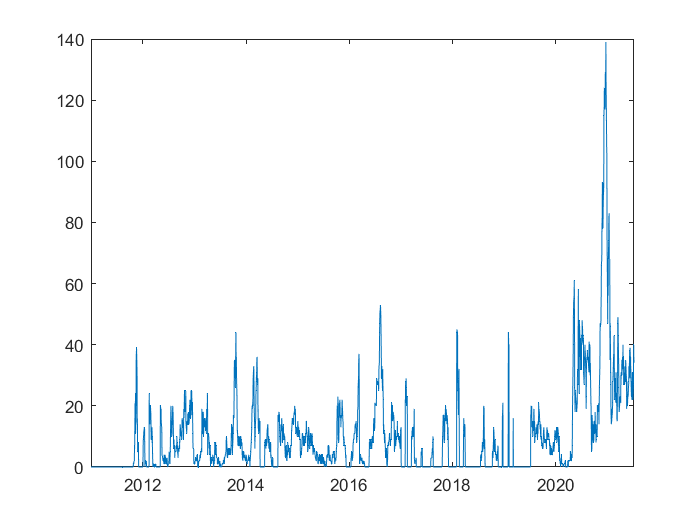

CombSignal = PriceTT ;
CombSignalVar = LiquiditySignal.Variables .* LowLiquidSignal.Variables ...
     .* PostSignBuffer.Variables .* StopLossSignal.Variables ;

CombSignal.Variables = CombSignalVar ;

FinalCombSignal = PriceTT;
FinalCombSignalVar = FinalCombSignal.Variables ;
FinalCombSignalVar  (2:end, :) = CombSignalVar (1:end-1, :);
FinalCombSignalVar (1, :) = 0 ;
FinalCombSignal.Variables = FinalCombSignalVar ;
% plot (FinalCombSignal.Time, FinalCombSignal.BBRI)

% Daily Signal
nDailySignal = sum(FinalCombSignalVar,2) ;
nDailySignalTT = timetable (FinalCombSignal.Time, nDailySignal, 'VariableNames',"nDailySignal") ;
plot (nDailySignalTT.Time, nDailySignalTT.Variables )



clear CombSignalVar FinalCombSignalVar

Build the strategy

% Create strategy object
TradingCosts ;
InitWeights = [] ;
RebalanceWeights = @(w,p,s) RebalanceWeightsFcn (w,p,s) ;
RebalanceFreq = 1 ;
LookbackWindSz = max ([MomContDays MomMainDays LiquidSurgAvgLeadDays LiquidSurgAvgLagDays StopLossLookbackWindSz] )

LookbackWindSz = 200


TrendTradeStrategy = backtestStrategy ('TrendTradeStrategy', ...
    RebalanceWeights, "RebalanceFrequency", RebalanceFreq, "TransactionCosts", ...
    TradingCosts, "LookbackWindow", LookbackWindSz, "InitialWeights", InitWeights)

TrendTradeStrategy =   backtestStrategy with properties:

                  Name: "TrendTradeStrategy"
          RebalanceFcn: @(w,p,s)RebalanceWeightsFcn(w,p,s)
    RebalanceFrequency: 1
      TransactionCosts: [0.0020 0.0030]
        LookbackWindow: 200
        InitialWeights: [1×0 double]



% setup backtest engine
riskFreerate = 0; 
cashBorrowrate = 0; 
InitPortfolioValue = 10^6 ; 

backtester = backtestEngine (TrendTradeStrategy, "RiskFreeRate", ...
    riskFreerate , "CashBorrowRate", cashBorrowrate, "InitialPortfolioValue", ...
    InitPortfolioValue) 

backtester =   backtestEngine with properties:

               Strategies: [1×1 backtestStrategy]
             RiskFreeRate: 0
           CashBorrowRate: 0
          RatesConvention: "Annualized"
                    Basis: 0
    InitialPortfolioValue: 1000000
                NumAssets: []
                  Returns: []
                Positions: []
                 Turnover: []
                  BuyCost: []
                 SellCost: []



% run the strategy backtest
startIdx = LookbackWindSz ;
endIdx = datetime ('09-Jul-2021')  ;

backtester = runBacktest (backtester, PriceTT, FinalCombSignal, ...
    'Start', startIdx) 

backtester =   backtestEngine with properties:

               Strategies: [1×1 backtestStrategy]
             RiskFreeRate: 0
           CashBorrowRate: 0
          RatesConvention: "Annualized"
                    Basis: 0
    InitialPortfolioValue: 1000000
                NumAssets: 665
                  Returns: [2415×1 timetable]
                Positions: [1×1 struct]
                 Turnover: [2415×1 timetable]
                  BuyCost: [2415×1 timetable]
                 SellCost: [2415×1 timetable]


Performance Analysis

% Summary 
summaryTable = summary (backtester) 

summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                0.2778    
    SharpeRatio               0.01425    
    Volatility               0.013562    
    AverageTurnover           0.16333    
    MaxTurnover               0.74172    
    AverageReturn          0.00019323    
    MaxDrawdown               0.62911    
    AverageBuyCost              280.3    
    AverageSellCost            419.44    


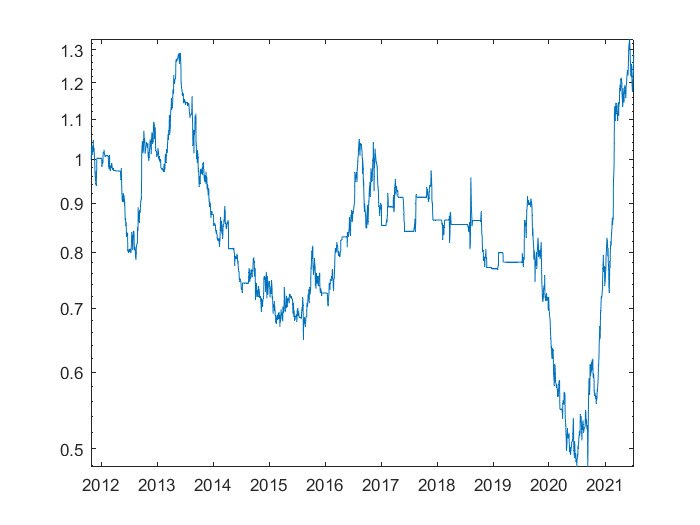

%Plot cumulative return 
dailyRet = backtester.Returns ; 
portfolioValue = ret2tick (dailyRet) ; 
% plot (portfolioValue.Time, portfolioValue.Variables) 
semilogy(portfolioValue.Time, portfolioValue.Variables) 

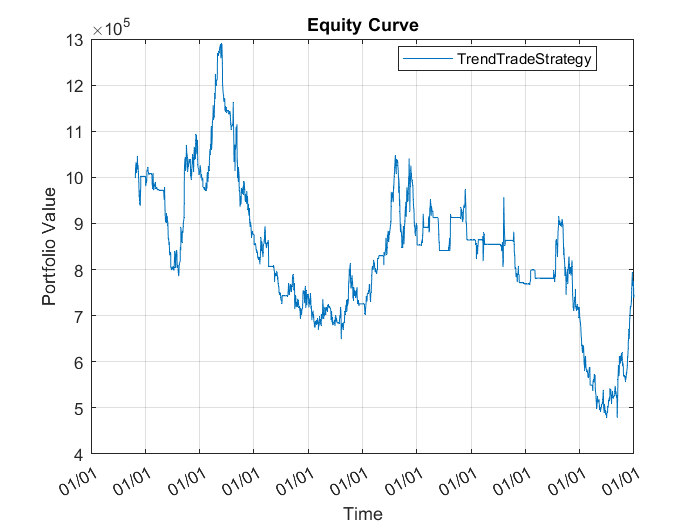

equityCurve(backtester) 


MAR = 0 ; 

% MaxDailyRet = max (DailyRetPort.Variables) ; 
% MinDailyRet = min (DailyRetPort.Variables) ; 
% a = CumSumPort.DailyReturnPort; 
EndCumSum = portfolioValue(end, :) 

EndCumSum = 1×1 timetable
       Time        TrendTradeStrategy
    ___________    __________________

    09-Jul-2021          1.2778      


% MaxCumSum = max (CumSumPort.DailyReturnPort) ; 
% MinCumSum = min (CumSumPort.DailyReturnPort) ; 

portfolioValueVar = portfolioValue.Variables ; 

TimePeriod = portfolioValue.Time ;
TradingPeriod = yearfrac (TimePeriod(1), TimePeriod(end))  

TradingPeriod = 9.6858

CAGR = portfolioValueVar(end) ^ (1/(TradingPeriod )) -1 

CAGR = 0.0256

% CAGR
% SharpeRatio = - sharpe(DailyRetPort.Variables, 0) * sqrt (250) ;
% SharpeRatio
% Sortino = - (mean(DailyRetPort.Variables) - MAR) / sqrt(lpm(DailyRetPort.Variables, MAR, 2)) * sqrt (250) ;
% Sortino 
% [MaxDD,MaxDDIndex] =  maxdrawdown (CumSumPort.DailyReturnPort); 
% MaxDD 
% StartEndMaxDD = b(MaxDDIndex) ;

% plot(PriceTT.Time, PriceTT.ARTO) 
% plot(PriceTT.Time, PriceTT.DCII) 
% plot(PriceTT.Time, PriceTT.DCII) 

% clear a b c 
 

Latest signal from last trading day

% LatestSignal = FinalCombSignal (end,:); 
% a = LatestSignal.Variables ; 
% b = LatestSignal.Properties.VariableNames ; 
% SymSignal = b(a>0); 
% SymSignal = cell2table (transpose(SymSignal) ) ; 
% SymSignal.Properties.VariableNames = "Symbols Signal"; 

% SymSignal ;
% clear a b 

Write signal to output file

% writetable (SymSignal, "Trend Trading Input Output Data.xlsx", 'sheet', "Output Data")

Check section

end
toc

Elapsed time is 23.868823 seconds.


Local Functions

Equally Weighted Rebalance Function

function new_weights = RebalanceWeightsFcn (Current_Weights ,PriceTT , SignalTT) 
% Compute weights based on most recent signal.

% Pull out the signal
CrossoverSignal = SignalTT.Variables ;

% Bet sizing
UninvestedAssets = sum (CrossoverSignal(end, :)) ;
MinNSymDivers = 6;

if UninvestedAssets <= MinNSymDivers 
    new_weights = CrossoverSignal(end,:) * (1 / MinNSymDivers) ;
    new_weights (isnan(new_weights)) = 0 ;
    new_weights (isinf(new_weights)) = 0 ;
    else
    new_weights = CrossoverSignal(end,:) * (1 / UninvestedAssets) ;
    new_weights (isnan(new_weights)) = 0 ;
    new_weights (isinf(new_weights)) = 0 ;

end

end
